# Compresión 2D por descomposición SVD

## Cargamos la imagen original

clc, clear, close all

% Leemos el mapa de bits que sale del microscopio
I = imread("onion.png");
I = rgb2gray(I);

% Determinamos dimensiones de la imagen
nx = size(I,1); ny = size(I,2);

% Observamos su tamaño real en memoria (2 BitDepth)
imwrite(I, "../outputs/FFT_real_I" + ".png");

## Cálculo FTT y compresión

% Inicializamos la figura
figure(1), clf, subplot(1,5,1);
imagesc(I), axis off, colormap gray
title("STEM img")

% Computamos la FFT en 2D usando fft2()
tic;
Yt=fft2(I); 
disp([' FFT done. (' num2str(toc) 's)'])

 FFT done. (0.0012719s)


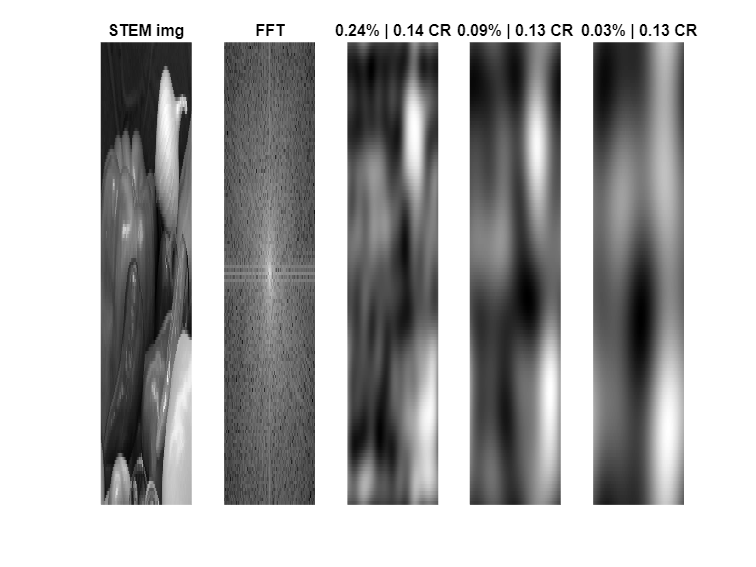


% Visualizamos los coeficientes FTT
F = log(abs(fftshift(Yt))+1);
F = mat2gray(F); % Escalado de la imagen entre 0 y 1
subplot(1,5,2)
imagesc(F), axis off
title("FFT")

% Lista de umbrales y storage de imágenes
delta_list = [0.02 0.05 0.1];
I_storage = uint16(zeros(nx,ny,length(delta_list)));

% Algoritmo de compresión para distintos umbrales
Max = max(max(abs(Yt)));

CR = zeros(length(delta_list),1);
bytes = zeros(length(delta_list),1);
dict = ["a", "b", "c"];

i=1;
for thresh = delta_list
    % Máscara umbral sobre los coeficientes FTT
    ind = abs(Yt) > thresh*Max; 
    Atlow = single(Yt .* ind);
    Ilow = uint8(ifft2(Atlow)); 
    
    % Aproximamos el tamaño en memoria
    Atlow_nonzero = nonzeros(Atlow');
    bytes_double = length(Atlow_nonzero)*4*2;         % single (4 bytes) - complex (x2)
    bytes_logic  = (nx*ny - length(Atlow_nonzero))/8; % logical (1 bit)
    bytes(i) = bytes_double + bytes_logic;

    % Comparamos frente al tamaño original
    I_nonzero = nonzeros(I');
    bytes_double = length(I_nonzero);           % uint8 (1 bytes) - real
    bytes_logic  = (nx*ny - length(I_nonzero))/8; % logical (1 bit)
    CR(i) = bytes(i)/(bytes_double + bytes_logic);
    
    % Porcentaje de coeficientes seleccionados
    count = nx*ny - sum(sum(ind));
    perc = 100 - count/(nx*ny)*100;
    
    % Guardamos la imagen final obtenida (en formato no comprimido)
    %imwrite(Ilow, "../outputs/FFT_Ilow" + num2str(perc,"%.2f") + ".tiff");
    I_storage(:,:,i) = Ilow;
    
    % Mostramos la imagen comprimida y su tamaño
    subplot(1,5,i+2), imagesc(Ilow), axis off
    title(dict(i) + ") " + num2str(perc,"%.2f") + "% | "+ num2str(CR(i),"%.2f CR") )

    i = i + 1;
end